# Problem 19-39

clear
constants

===== Start of script constants.m =====


NA =      6.02e+23

R =          8.31

k =    1.3804e-23

torr2pa =        133.32

===== End of script constants.m =====


Escape speeds and molar masses

vesc_Earth = 11.2e3 % escape speed from Earch = 11.2 km/s

vesc_Earth =        11200

vesc_Moon = 2.38e3  % escape speed from Moon = 2.38 km/s

vesc_Moon =         2380

M_H2 = 2*1.00797e-3 % atomic molar mass of hydrogen is 1.00797 g/mol

M_H2 =     0.0020159

M_O2 = 2*15.9994e-3 % atomic molar mass of oxygen is 15.9994 g/mol

M_O2 =      0.031999

$v_{rms} = \sqrt{\frac{3RT}{M}}$ thus $T = \frac{v_{rms}^2 M}{3R}$

At what temperature does the rms speed of 

(a) $H_2$ (molecular hydrogen) equal the escape speed from Earth

T_H2 = vesc_Earth^2*M_H2/(3*R) % K

T_H2 =         10144

(b) $O_2$ (molar oxygen)

T_O2 = vesc_Earth^2*M_O2/(3*R) % K

T_O2 =    1.6101e+05

At what temperature does the rms speed of 

(c) $H_2$ (molecular hydrogen) equal the escape speed from Moon

T_H2 = vesc_Moon^2*M_H2/(3*R) % K

T_H2 =        458.05

(d) $O_2$ (molar oxygen)

T_O2 = vesc_Moon^2*M_O2/(3*R) % K

T_O2 =        7270.5

Should there be much 

(e) hydrogen high in Earth's upper atmosphere where the temperature is about 1000K?

syms v real positive
T = 1000        % temperature at upper atmosphere

T =         1000

P_H2 = 4*pi*(M_H2/(2*pi*R*T))^(3/2)*v^2*exp(-M_H2*v^2/(2*R*T));
frac_H2 = vpa(int(P_H2,v,[vesc_Earth Inf]),3)

$$frac\_H2 = 1.12e-6$$

(f) oxygen

P_O2 = 4*pi*(M_O2/(2*pi*R*T))^(3/2)*v^2*exp(-M_O2*v^2/(2*R*T));
frac_O2 = vpa(int(P_O2,v,[vesc_Earth Inf]),3)

$$frac\_O2 = 0.0$$

Maxwellian distribution of $H_2$ and $O_2$ at T = 1000K

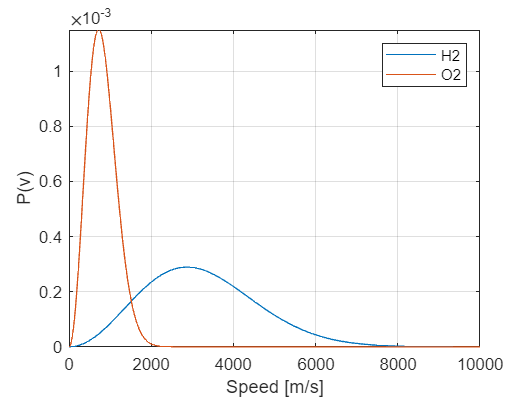

fplot([P_H2, P_O2],[0 10000]), grid on
legend('H2','O2'), xlabel('Speed [m/s]'), ylabel('P(v)')

#### [ANSWER] Very fewer oxygen molecules escape than hydrogen molecules do